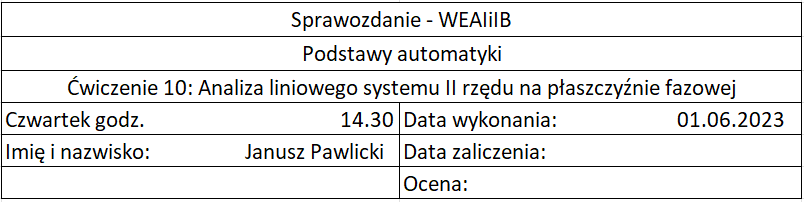

## 1. Wstęp

Metoda płaszczyzny fazowej polega na poszukiwaniu wozwiązania dynamicznego równania ruchu nie jako funkcji czasu, lecz w postaci zależności między prędkością a przemieszczeniem. Metoda płaszczyzny fazowej pozwala określić podstawowe właściwości ruchu bez potrzeby rozwiązywania wyjściowych równań ruchu w dziedzinie czasu. Najwygodniej jest ją stosować, gdy dysponuje się maszyną analagową z ploterem lub oscyloskopem.

## 2. Przebieg laboratorium

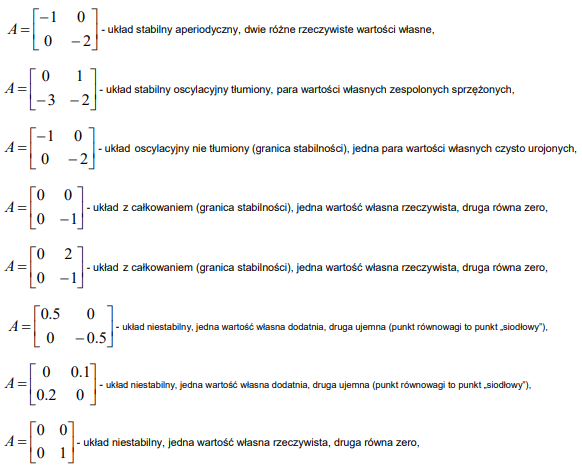

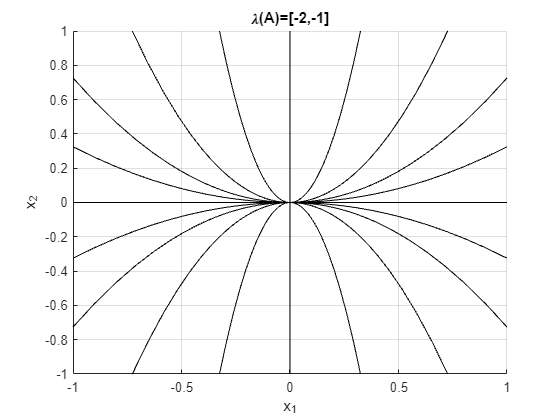

% układ stabilny aperiodyczny, dwie różne rzeczywiste wartości własne
A = [-1,0;0,-2];
T=6; 
[w J]=eig(A); 
figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);

for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end
hold off

% układ stabilny oscylacyjny tłumiony, para wartości własnych zespolonych sprzężonych
A=[0,1;-3,-2];
T=6; 
[w J]=eig(A); 
figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);

for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

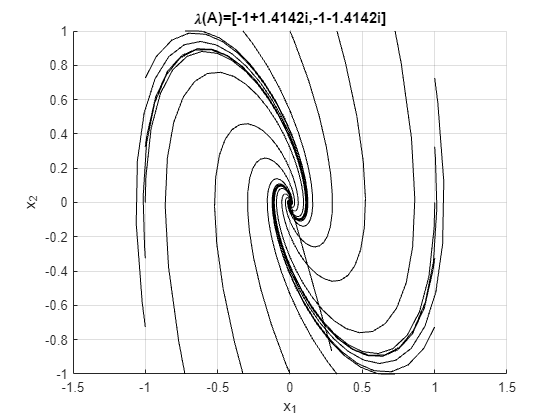

hold off

% układ oscylacyjny nie tłumiony (granica stabilności), jedna para wartości własnych czysto urojonych
A = [0,1;-1,0];
T=6; 
[w J]=eig(A); 
figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);

for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

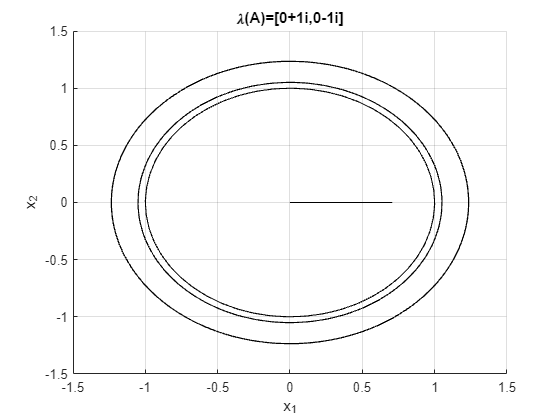

hold off

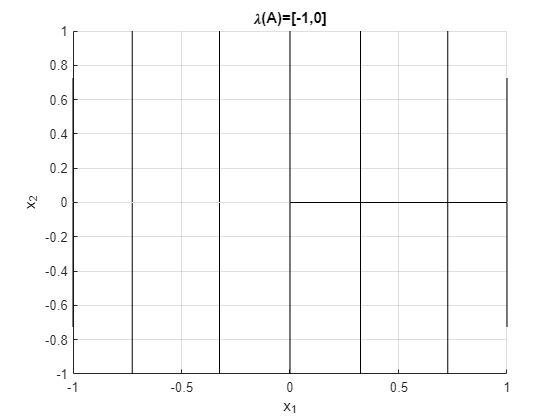

%  układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero
A = [0,0;0,-1];
T=6; 
[w J]=eig(A); 
figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);

for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end
hold off

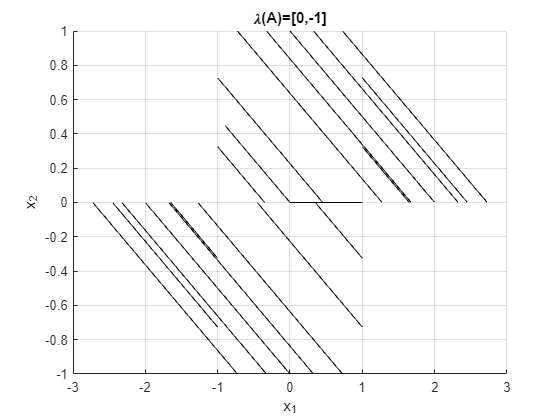

% układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero
A = [0,2;0,-1];
T=6; 
[w J]=eig(A); 
figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);

for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end
hold off

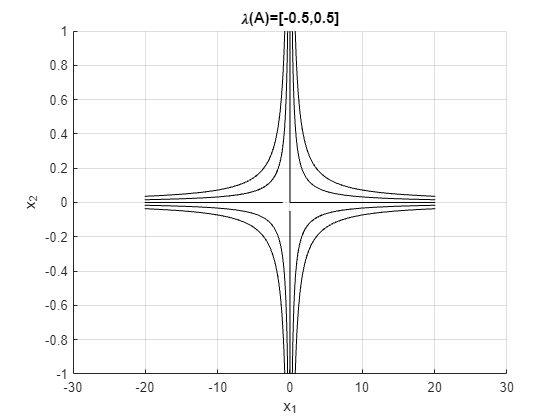

% układ z całkowaniem (granica stabilności), jedna wartość własna rzeczywista, druga równa zero
A = [0.5 0;0,-0.5];
T=6; 
[w J]=eig(A); 
figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);

for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end
hold off

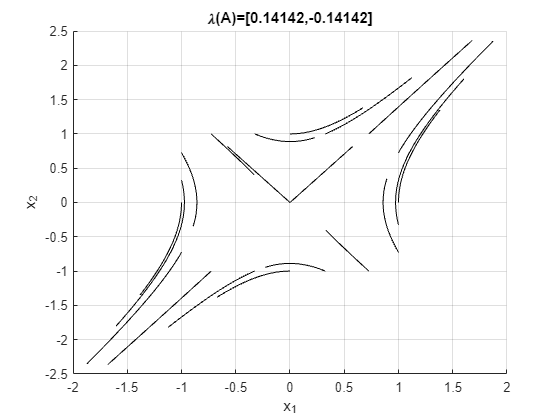

% - układ niestabilny, jedna wartość własna dodatnia, druga ujemna (punkt równowagi to punkt „siodłowy”)
A = [0,0.1;0.2,0];
T=6; 
[w J]=eig(A); 
figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);

for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end
hold off

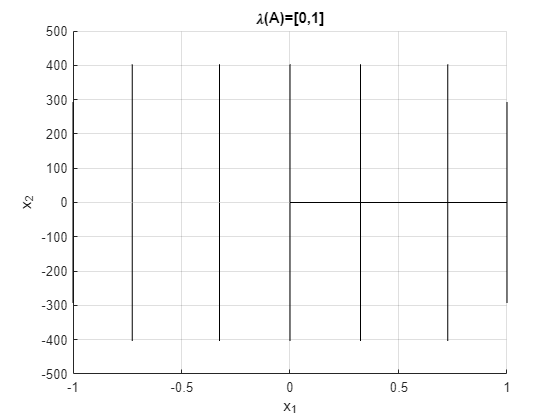

% układ niestabilny, jedna wartość własna rzeczywista, druga równa zero
A = [0 0;0,1];
T=6; 
[w J]=eig(A); 
figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);

for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end
hold off

## 3. Wnioski

Ćwiczenie pozwoliło nam na zaobserowanie zachowań różnych układów na płaszczyźnie fazowej:

- Dla układu aperiodycznego linie wykresu zmierzaj w kierunku środka układu co oznacza że obiekty wyłączone z równowagi wracają do niej.

- Układ stabilny oscylacyjny tłumiony również zmierza do punktu równowagi, ale w porównaniu do poprzedniego robi to wolniej. Przebieg układu oscylacyjnego nietłumionego oscyluje ze stałą amplitudą wokół punktu równowagi, ale nie zmierza do niego.

- Dwa kolejne układy różnią się zmienną, która jest całkowana: pierwszy jest całkowaniem względem zmiennej x2, natomiast drugi całkowaniem względem x1 oraz x2.

- Układy z trzech ostatnich podpuktów są układami niestabilnymi, ponieważ po ich przebiegach na płaszczyźnie fazowej można zauważyć, że po wtrąceniu punktu równowagi nie wracają do niego. 